% %Func 1
% fun_1 = piecewise(abs(t)<=b, a, abs(t)>b, 0);
% fourier_1 = a*exp(-1i*w*t);
% ans_1 = (1/sqrt(2*pi))*int(fourier_1, t, [-b b]);
% 
% f_1 = figure;
% fplot(ans_1, [-10 10])
% hold on
% fplot(fun_1)
% grid on
% xlabel("t, \omega")
% legend('c(\omega)', 'f(t)')
% text(-9,7,sprintf('a = %d,   b = %d', a, b), 'Color','red','FontSize',12)
% saveas(f_1,'C:\LATEX\Fourier_analiz\Fourier_2\1_3.png');

% a = 3

a = 3

% b = 6

b = 6

% syms t w
% %Func 2
% fun = (a-abs(a*t/b))*exp(-t*1i*w);
% anss = (1/sqrt(2*pi))*int(fun, t, [-b b])

$$anss = -\frac{7186705221432913\,\left(\cos\left(6\,w\right)-1\right)}{18014398509481984\,w^{2}}$$

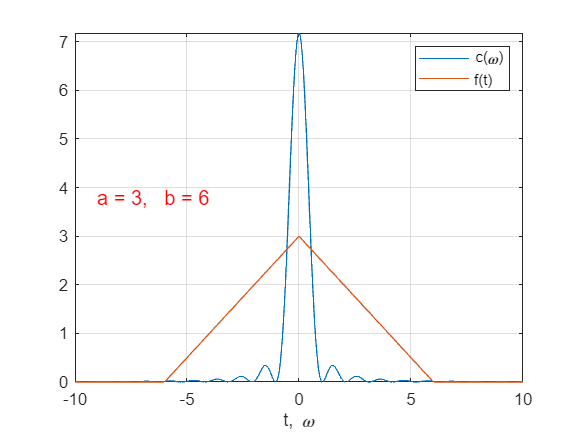

% y = piecewise(abs(t)<=b, a-abs(a*t/b), abs(t)>b, 0);
% 
% f = figure;
% fplot(anss, [-10 10])
% hold on
% fplot(y)
% grid on
% xlabel("t, \omega")
% legend('c(\omega)', 'f(t)')
% text(-9,3.8,sprintf('a = %d,   b = %d', a, b), 'Color','red','FontSize',12)

% saveas(f,'C:\LATEX\Fourier_analiz\Fourier_2\2_3.png');

% a = 2
% b = 5
% syms t w
% %Func 3
% y = a*sin(b*t*pi)/(b*t*pi);
% anss = piecewise(abs(w)<=b*pi, a/(sqrt(2*pi*b^2)), abs(w)>b*pi, 0);
% 
% f = figure;
% fplot(anss, [-17 17])
% hold on
% fplot(y)
% grid on
% xlabel("t, \omega")
% legend('c(\omega)', 'f(t)')
% text(-14,1.8,sprintf('a = %d,   b = %d', a, b), 'Color','red','FontSize',12)
% saveas(f,'C:\LATEX\Fourier_analiz\Fourier_2\3_3.png');

% a = 5

a = 5

% b = 0.5

b = 0.5000

% syms t w
% %Func 4
% fun_4 = a*exp(-b*t^2)*exp(-t*1i*w);
% anss = int(fun_4, t, [-Inf Inf])

$$anss = 5\,\sqrt{2}\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{w^{2}}{2}}$$

% y = a*exp(-b*t^2)

$$y = 5\,{\mathrm{e}}^{-\frac{t^{2}}{2}}$$

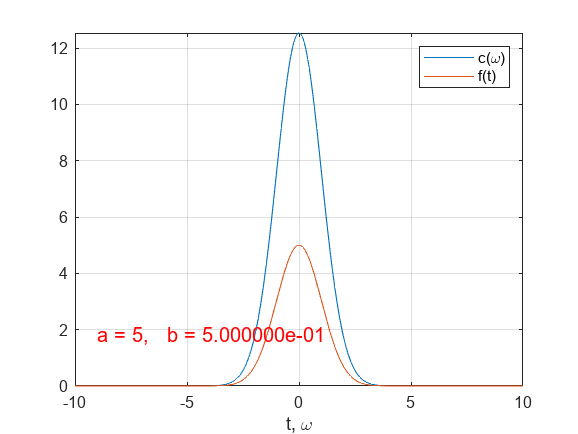

% 
% f = figure;
% fplot(anss, [-10 10])
% hold on
% fplot(y)
% grid on
% xlabel("t, \omega")
% legend('c(\omega)', 'f(t)')
% text(-9,1.8,sprintf('a = %d,   b = %d', a, b), 'Color','red','FontSize',12)

% saveas(f,'C:\LATEX\Fourier_analiz\Fourier_2\4_3.png');

% a = 0.5
% b = 0.5
% syms t w
% %Func 5
% % fun_5 = a*exp(-b*abs(t))*exp(-t*1i*w);
% % anss = (1/sqrt(2*pi))*int(fun_5, t, [-Inf Inf]);
% anss = sqrt(2/pi)*(b*a/(b^2+w^2));
% y = a*exp(-b*abs(t));
% 
% f = figure;
% fplot(anss, [-10 10])
% hold on
% fplot(y)
% grid on
% ylim([0 2])
% xlabel("t, \omega")
% legend('c(\omega)', 'f(t)')
% text(-9,1.8,sprintf('a = %d,   b = %d', a, b), 'Color','red','FontSize',12)
% saveas(f,'C:\LATEX\Fourier_analiz\Fourier_2\5_3.png');

%Complex
% c = 8;
% syms t w;
% 
% anss_re = real(1.5*exp(w*(c*1i-w/8)));
% anss_im = imag(1.5*exp(w*(c*1i-w/8)));
% anss_mod = sqrt(imag(1.5*exp(w*(c*1i-w/8)))^2 + real(1.5*exp(w*(c*1i-w/8)))^2);
% y = 3*exp(-2*(t+c)^2);
% 
% f = figure;
% hold on
% fplot(anss_re, [-7 7])
% fplot(anss_im, [-7 7])
% fplot(y)
% fplot(anss_mod, [-7 7])
% grid on
% % ylim([0 2])
% xlabel("t, \omega")
% legend('$Re(\hat g(\omega))$', '$Im(\hat g(\omega))$','$g(t)$','$|\hat g(t)|$','Interpreter','latex')
% text(-7,1.8,sprintf('c = %d', c), 'Color','red','FontSize',12)
% % saveas(f,'C:\LATEX\Fourier_analiz\Fourier_2\comp_4.png');